clc; clear all; close all;
% 线性系统系数矩阵
A=[1 1; 0 1]; B=[1; 0.5];
% 初始状态量-如果不能在下一步回到约束范围内，则会造成无解
x0=[4; 0];
% 预测步长
Np=5;
% 优化目标参数，加权矩阵
Q=eye(2); R=1;
% 转化为用控制量ut表示的，关于状态量的推导方程的矩阵
At=[]; Bt=[]; temp=[];
% 转换后的加权矩阵
Qt=[]; Rt=[];

% 加权矩阵的计算过程，以及推导方程矩阵的叠加过程
for i=1:Np
        At=[At; A^i];
        Bt=[Bt zeros(size(Bt,1), size(B,2));
            A^(i-1)*B temp];
        temp=[A^(i-1)*B temp];
        
        Qt=[Qt zeros(size(Qt,1),size(Q,1));
            zeros(size(Q,1),size(Qt,1)) Q];
        Rt=[Rt zeros(size(Rt,1),size(R,1));
            zeros(size(R,1),size(Rt,1)) R];
end
% 控制量ut的上下限
lb=-1*ones(Np,1);
ub=1*ones(Np,1);
% 控制量ut的初始值
u0=zeros(Np,1);
% 转换后的优化目标函数矩阵，循环优化函数中H后的表达式为优化目标的另一项
H=2*(Bt'*Qt*Bt + Rt);

% 转换后的优化中的不等式约束左边系数矩阵，后面循环中的bi为不等式右边
Ai=[Bt; -Bt];
% 声明u来保存每一步采用的控制量
u=[];
x=x0;
xk=x0;


for k=1:50
    
    % 关于ut的不等式约束，实际上约束的是状态量，常数4就是状态量约束的上下边界
    bi=[5-At*xk; 5+At*xk];
    f=2*xk'*At'*Qt*Bt;
    % 一切准备就绪，进行二次优化
    [ut, fval, exitflag]=quadprog(H,f',Ai,bi,[],[],lb,ub,u0);
    % 显示求解结果是否正常
    fprintf('%d\n', exitflag)

    % 采用优化得到的控制量的第一个元素作为实际作用的控制量，代入到原系统中得到下一个时刻的状态量
    u(k) = ut(1);
    x(:, k+1) = A*x(:, k) + B*u(k);
    xk = x(:, k+1);
    % 对优化初始值进行修改，采用预测值的后段作为下一步的初始值
    u0 = [ut(2:Np); ut(Np)];
    
end

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


1


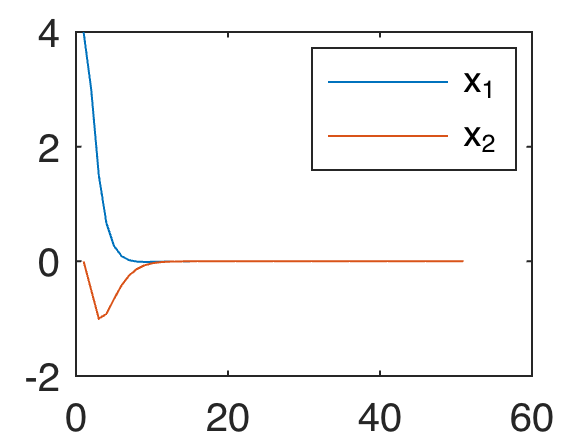



figure();
plot(x');
legend('x_1','x_2');

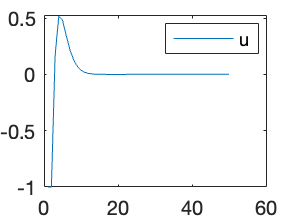


figure();
plot(u);
legend('u');